%Analysis V2
clear
tic

% Import data from text file
%TimeTemp = readtable("\\apporto.com\dfs\UHCL\Users\1915097_uhcl\Documents\Thesis\TimeTemp.csv");
%TimeTemp = readtable("\\apporto.com\dfs\UHCL\Users\1915097_uhcl\Documents\Thesis\TimeTemp_2026_Sep_06_Sun_13_59_53.csv");
%TimeTemp = readtable("\\apporto.com\dfs\UHCL\Users\1915097_uhcl\Documents\Thesis\TimeTemp_2026_Sep_07_Mon_10_00_49.csv");
TimeTemp = readtable("\\apporto.com\dfs\UHCL\Users\1915097_uhcl\Documents\Thesis\TimeTemp_2026_Sep_08_Tue_14_31_01.csv");
toc

Elapsed time is 1.862119 seconds.


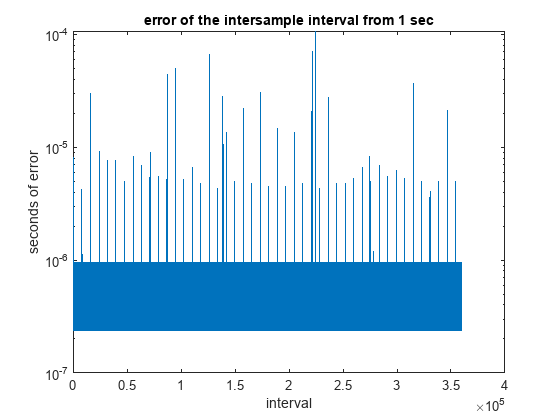

% Calculate intersample interval
dt = diff(TimeTemp{:,"now"});

% Plot the intersample interval
figure(); plot(dt-1);title("error of the intersample interval from 1 sec"); ylabel("seconds of error");xlabel("interval");
set(gca,'XScale','linear','YScale','log');

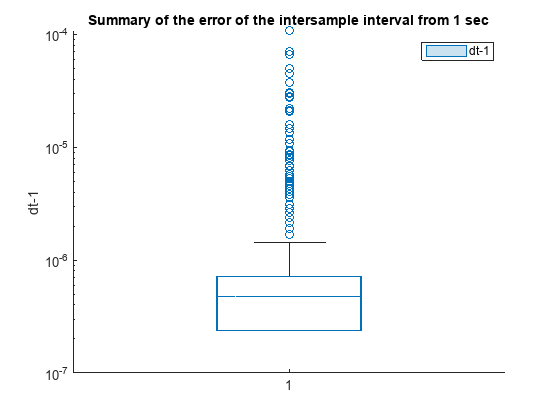


% % Create boxchart of dt
figure(); boxchart(dt-1,'Notch','on',"DisplayName","dt-1");
% Add ylabel, title, and legend
ylabel("dt-1");
title("Summary of the error of the intersample interval from 1 sec")
set(gca,'YScale','log');
legend

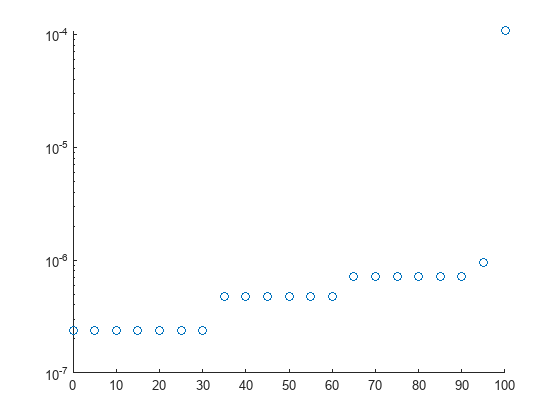


percentiles = 0:5:100;
figure();
scatter(percentiles,prctile(dt-1,percentiles));
set(gca,'XScale','linear','YScale','log');

toc

Elapsed time is 2.428737 seconds.


%compute the Allan Variance of the Intersample Interval Duration with a 
dt_tau = 1:100:height(dt)/2;
time0=toc

time0 = 3.7784

dt_avar=allanvar(dt,dt_tau); % tau channel
% time1=toc
% dt_avarcust=allanVarCustom(dt,dt_tau)
% time2=toc
% dt_avarvec=allanVarVectorized(dt,dt_tau)
% time3=toc
% runtime1 = time1-time0
% runtime2 = time2-time1
% runtime3 = time3-time2
%Compute the slope of the clock Allan Variance over Tau
idx = dt_tau >= 1 & dt_tau <= 1000;   % sample region

% linear fit in log10-log10 space; 
p = polyfit(log10(dt_tau(idx)), log10(dt_avar(idx)), 1);

%create the best fit line
yfit = 10.^(p(1)*log10(dt_tau) + p(2)); 

%Predict the taus
predictionTaus = 10.^[0;1;2;3;4;5;6];
predictedJitter = 10.^(p(1)*log10(predictionTaus) + p(2));
table(predictionTaus,predictedJitter)

ans = 7×2 table
    predictionTaus    predictedJitter
    ______________    _______________

            1           1.4016e-13   
           10           1.4686e-14   
          100           1.5388e-15   
         1000           1.6123e-16   
        10000           1.6893e-17   
        1e+05             1.77e-18   
        1e+06           1.8546e-19   


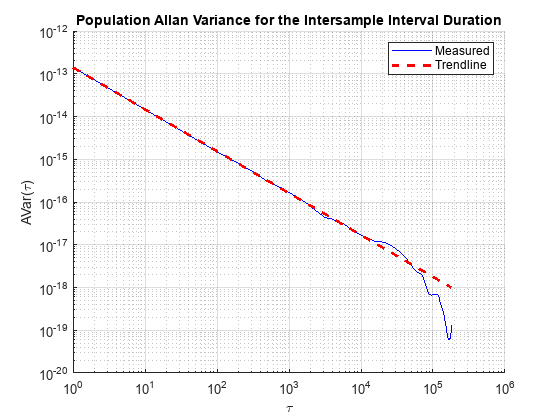


%Plot the Allan Variance of the clock
figure(); hold on;
plot(dt_tau, dt_avar, 'b');
% scatter(dt_tau,dt_avarcust,'g');
%scatter(dt_tau,dt_avarvec,"cyan")
plot(dt_tau, yfit, 'r--', 'LineWidth', 2);
title("Population Allan Variance for the Intersample Interval Duration");
xlabel('\tau'); ylabel('AVar(\tau)');
legend("Measured", "Trendline");
set(gca,'XScale','log','YScale','log');
grid on;hold off;

disp("LogLog Slope:" + p(1)) % p(1) = slope;

LogLog Slope:-0.97973


disp("LogLog Intercept:" + p(2)) % p(2) = intercept;

LogLog Intercept:-12.8534


disp("AVAR(\tau)=" + p(2) +"\tau^"+ p(1))

AVAR(\tau)=-12.8534\tau^-0.97973


toc

Elapsed time is 7.008366 seconds.


%Create a shortcut to point to the rawdata
allsensors = ["Temp1","Temp2","Temp3","Temp4","Temp5","Temp6","Temp7","Temp8"];
%take the moving average after eliminating outliers from the moving median
% 0. Compute the Per Row Median
TimeTemp{:,"median"}=median(TimeTemp{:,allsensors},2);
% 1. Compute deviation from median
TimeTemp{:,"MedianDifference"} = abs(TimeTemp{:,allsensors} - TimeTemp{:,"median"});
% 2. Build mask of good sensors
TimeTemp{:,"mask"} = TimeTemp{:,"MedianDifference"} <= 0.25;   % Nx8 logical
% 3. Zero out bad sensors
TimeTemp{:,"goodVals"} = TimeTemp{:,allsensors} .* TimeTemp{:,"mask"};
% 4. Count good sensors per row
TimeTemp{:,"numGood"} = sum(TimeTemp{:,"mask"}, 2);
% 5. Compute robust average
robustAvg = sum(TimeTemp{:,"goodVals"}, 2) ./ TimeTemp{:,"numGood"};
% 6. Handle rows with zero good sensors
robustAvg(TimeTemp{:,"numGood"} == 0) = NaN;
TimeTemp{:,"robustAvg"}=robustAvg;

clear robustAvg
% Smooth robustAvg data
[TimeTemp.robustAvgSmoothGauss,winSize] = smoothdata(TimeTemp{:,"robustAvg"},"gaussian",120, ...
    "SamplePoints",TimeTemp.now);

noise = TimeTemp{:,allsensors} - TimeTemp.robustAvgSmoothGauss;

% TimeTemp{:,"MovingMean"} = movmean(TimeTemp{:,allsensors},120);
% TimeTemp{:,"Noise"} = TimeTemp{:,allsensors}-TimeTemp{:,"MovingMean"};
% features = table
% features {"Mean",:} = mean(TimeTemp{:,"Noise"});
% features {"StdDev",:} = std(TimeTemp{:,"Noise"});
% features {"Skew",:} = skewness(TimeTemp{:,"Noise"});
% features {"kurt",:} = kurtosis(TimeTemp{:,"Noise"});
% features {"rms",:} = rms(TimeTemp{:,"Noise"});
% features {"mad",:} = mad(TimeTemp{:,"Noise"});
% features {"iqr",:} = iqr(TimeTemp{:,"Noise"});
% features.Properties.VariableNames = allsensors

% AC1 = zeros(nSensors,1);
% AC10 = zeros(nSensors,1);
% 
% for k = 1:nSensors
% 
%     x = noise(:,k);
% 
%     r = xcorr(x,10,'coeff');
% 
%     AC1(k)  = r(12);   % lag = 1
%     %2,4,7
%     AC10(k) = r(end);  % lag = 10
%     %20 40 70 100
%     %I want to see a lag sweep similar to the E6 or E12 scale for resistors
% 
% end
% 
% features.AC1 = AC1;
% features.AC10 = AC10;

function features = SubSectionTimeDomain(noise,allsensors)
    features = table();
    features.SensorName = allsensors';

    features.Mean     = mean(noise)';
    features.StdDev   = std(noise)';
    features.Skew     = skewness(noise)';
    features.Kurtosis = kurtosis(noise)';
    features.RMS      = rms(noise)';
    features.MAD      = mad(noise)';
    features.IQR      = iqr(noise)';
    
    % features.Properties.RowNames = allsensors;
end

function features = SubSectionAutocorrelation(noise,allsensors)
    features = table();
    features.SensorName = allsensors';

    nSensors = length(allsensors);
    %12/decade * (4-0)Decades +1 end = 12*4+1
    powers = [0 4]; perdecade = 12;
    lags = unique(round(logspace(powers(1),powers(2),diff(powers)*perdecade+1)));
    
    for k = 1:nSensors
        x = noise(:,k);
        maxLag = max(lags);
        r = xcorr(x,maxLag,'coeff');
        zeroLag = maxLag+1;
        for n = 1:length(lags)
            lag = lags(n);
            features{k,...
                sprintf('AC_%d',lag)} = ...
                r(zeroLag+lag);
        end
    end
    % features.Properties.RowNames = allsensors;
end

function features = SubsectionPowerSpectralDensity(noise,allsensors)
    features = table();
    features.SensorName = allsensors';

    nSensors = length(allsensors);

    Fs = 1;   % Replace with actual sample rate
    centroid  = zeros(nSensors,1);
    spectralVar = zeros(nSensors,1);
    spectralSkew = zeros(nSensors,1);
    peakfreq  = zeros(nSensors,1);
    totpower  = zeros(nSensors,1);
    entropyPSD = zeros(nSensors,1);
    noiseSlope = zeros(nSensors,1);
    noiseIntercept = zeros(nSensors,1);
    
    fBands = [
    0      0.001;
    0.001  0.003; 0.003 0.005; 0.005 0.01;
    0.01   0.03; 0.03   0.05;  0.05  0.1;
    0.1    0.3;  0.3    0.5;   0.5   1;
    ];
    bandEnergy = zeros(nSensors,size(fBands,1));
    
    for k = 1:nSensors
        [pxx,f] = pwelch(noise(:,k),[],[],[],Fs);
    
        centroid(k) = sum(f.*pxx)/sum(pxx);%Spectral Mean
        spectralVar(k) = sum((f-centroid(k)).^2 .* pxx)/sum(pxx);%Spectral Variance
        spectralSkew(k) = sum((f-centroid(k)).^3 .* pxx)/(sum(pxx)*spectralVar(k)^(1.5)); %SpectralSkew
    
        [~,idx] = max(pxx);
        peakfreq(k) = f(idx);
        totpower(k) = bandpower(pxx,f,'psd');
        
        valid = f > 0;
        p = polyfit(log10(f(valid)),log10(pxx(valid)),1);
        noiseSlope(k) = p(1);
        noiseIntercept(k) = p(2);
        
        for b = 1:size(fBands,1)
            idx = f >= fBands(b,1) & ...
                  f <  fBands(b,2);
            bandEnergy(k,b) = sum(pxx(idx));
        end
    end
    
    for k = 1:nSensors
        [pxx,~] = pwelch(noise(:,k));
        p = pxx/sum(pxx);
        entropyPSD(k) = -sum(p.*log2(p+eps));
    end

    features.SpectralCentroid = centroid;
    features.SpectralVariance = spectralVar;
    features.SpectralSkew = spectralSkew;
    features.PeakFreq = peakfreq;
    features.TotalPower = totpower;
    features.SpecEntropy = entropyPSD;
    features.OneOverF_Slope = noiseSlope;
    features.OneOverF_Intercept = noiseIntercept;
    
    for b = 1:size(fBands,1)
        features.(sprintf('FFTBand_%d',b)) = bandEnergy(:,b);
    end

    % features.Properties.RowNames = allsensors;

    % plot all eight PSDs on the same log-log axes.
    % figure;
    % hold on
    % for k = 1:nSensors
    %     [pxx,f] = pwelch(noise(:,k),[],[],[],Fs);
    %     plot(f,pxx)
    % end
    % hold off
    % legend(allsensors,"Location","northwest")
    % grid on
    % set(gca,'XScale','log','YScale','log');
    % xlabel('Frequency');ylabel('PSD');title('Sensor Noise Spectra')
end

%Pending for PSD
% [pks,locs] = findpeaks(pxx,f,...
%     'SortStr','descend');
% 
% NPeaks = min(5,length(pks));
% Peak1Freq
% Peak1Mag
% Peak2Freq
% Peak2Mag
% ...

% fftFrequencies = [
% 1e-4
% 2e-4
% 5e-4
% 1e-3
% 2e-3
% 5e-3
% 1e-2
% 2e-2
% 5e-2
% 1e-1
% ];
%Interpolate the PSD:
% psdSample = interp1(f,pxx,...
%                     fftFrequencies,...
%                     'linear',...
%                     'extrap');


function features = SubSectionAllanVariance(noise,allsensors)
    features = table();
    features.SensorName = allsensors';
    nSensors = length(allsensors);

    % AllanMin = zeros(nSensors,1);
    % AllanMinTau = zeros(nSensors,1);
    
    %tau_in = 1:height(noise)/2;
    tau_in= unique(round(2.^(0:log2(size(noise,1)/2)/1000:log2(size(noise,1)/2))));
    [avar,tau]=allanvar(noise,tau_in); % tau channel
    
    [AllanMin,idx] = min(avar,[],1);
    AllanMinTau = tau(idx);
    
    AllanSlope = zeros(nSensors,1);
    AllanIntercept = zeros(nSensors,1);
    for k = 1:nSensors
        p = polyfit(log10(tau),log10(avar(:,k)),1);
        AllanSlope(k) = p(1);
        AllanIntercept(k) = p(2);
    end
    
    features.AllanMin = AllanMin';
    features.AllanMinTau = AllanMinTau;
    features.AllanSlope = AllanSlope;
    features.AllanIntercept = AllanIntercept;
    
    for m = 1:length(tau)
        features.(sprintf('AVar_Tau_%d',tau(m))) = avar(m,:)';
    end
    
    % features.Properties.RowNames = allsensors;
    
    % figure
    % plot(tau,avar)
    % grid on;
    % legend
    % xlabel("tau");ylabel("Variance");
    % set(gca,'XScale','log','YScale','log');
end


function features=FingerprintMetaFunction(noise,allsensors)
    warning('off','all')
    features1 = SubSectionTimeDomain(noise,allsensors);
    features2 = SubSectionAutocorrelation(noise,allsensors);
    features3 = SubsectionPowerSpectralDensity(noise,allsensors);
    features4 = SubSectionAllanVariance(noise,allsensors);
    features12 = join(features1,features2);
    features34 = join(features3,features4);
    features = join(features12,features34);
    warning('on','all')
end

features=FingerprintMetaFunction(noise,allsensors)

features = 8×769 table
    SensorName      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681     AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance

Xraw = table2array(removevars(features,"SensorName"));
% Remove non-informative columns
goodCols = std(Xraw,0,1) > 0;
X = Xraw(:,goodCols);

%inspect the removed columns
featureNames = features.Properties.VariableNames;
badCols = not(goodCols);
featureNames(badCols)

ans = 1×1 cell array
    {'SpectralSkew'}


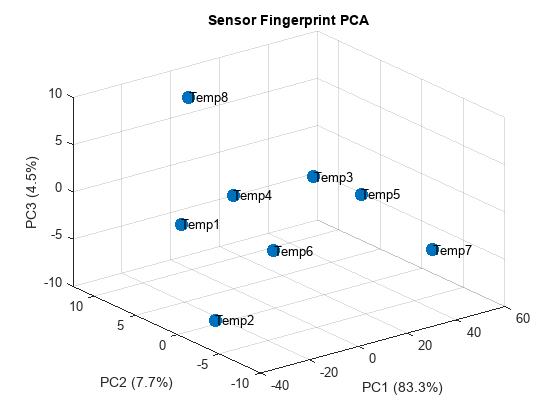


% Normalize remaining columns
X = normalize(X);

[coeff,score,~,~,explained] = pca(X);

figure
scatter3(score(:,1),score(:,2),score(:,3),100,'filled')

text(score(:,1),score(:,2),score(:,3),allsensors)

xlabel(['PC1 (' num2str(explained(1),'%.1f') '%)'])
ylabel(['PC2 (' num2str(explained(2),'%.1f') '%)'])
zlabel(['PC3 (' num2str(explained(3),'%.1f') '%)'])
title('Sensor Fingerprint PCA')
grid on

%Rolling on the data
maxpts = 600; %seconds of window
windowpoints = 0:maxpts-1;
seconds=height(noise)-maxpts;
slices = 1:maxpts/2:seconds;
nWindows=length(slices)

nWindows = 1198


for i=1:nWindows
    t=slices(i);
    noisewindow = noise(t+windowpoints,:);
    Features(i).Data = FingerprintMetaFunction(noisewindow,allsensors);
end

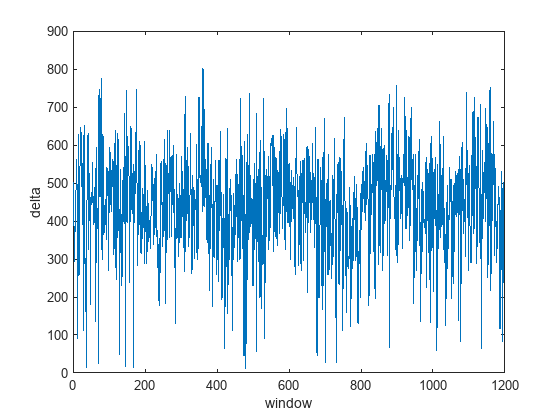

for i = 1:nWindows-1
    F1 = table2array(removevars(Features(i).Data,"SensorName"));
    F2 = table2array(removevars(Features(i+1).Data,"SensorName"));
    
    delta(i) = norm(F2-F1,'fro');
end
plot(delta)
xlabel("window")
ylabel("delta")

AllRows = [];
RejectedCols=['SensorName'];

for i = 1:nWindows
    F = removevars(Features(i).Data,'SensorName');
    VarNames = F.Properties.VariableNames;
    X = table2array(F);
    
    badcols = std(X)==0;
    if any(badcols)
        fprintf("Window %d has %d constant cols\n", ...
        i,sum(badcols));
        VarNames(badcols)
    end
end

F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147       AC_215        AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 1 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46       AC_68     AC_100      AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 2 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1       AC_2       AC_3       AC_5       AC_7       AC_10       AC_15      AC_22      AC_32       AC_46       AC_68      AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 3 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 4 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 5 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1        AC_2        AC_3        AC_5       AC_7       AC_10       AC_15       AC_22       AC_32       AC_46        AC_68        AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    S

Window 6 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 7 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 8 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 9 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100       AC_147       AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 10 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 11 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 12 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 13 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 14 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46       AC_68       AC_100      AC_147       AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 15 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 16 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 17 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 18 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 19 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1        AC_2       AC_3       AC_5        AC_7       AC_10       AC_15       AC_22       AC_32       AC_46        AC_68       AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spe

Window 20 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 21 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100       AC_147       AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 22 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46       AC_68        AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 23 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46      AC_68      AC_100       AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 24 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1        AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 25 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215        AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 26 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 27 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 28 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 29 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 30 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3        AC_5        AC_7       AC_10       AC_15       AC_22       AC_32       AC_46       AC_68       AC_100      AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spect

Window 31 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 32 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 33 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 34 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 35 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSke

Window 36 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 37 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 38 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 39 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 40 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 41 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 42 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 43 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 44 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2       AC_3        AC_5       AC_7       AC_10       AC_15        AC_22       AC_32        AC_46        AC_68         AC_100       AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 45 has 9 constant cols


ans = 1×9 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 46 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSke

Window 47 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100       AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSke

Window 48 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 49 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 50 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 51 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 52 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 53 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 54 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 55 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 56 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 57 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 58 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 59 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 60 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68        AC_100       AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSke

Window 61 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15       AC_22       AC_32      AC_46       AC_68       AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 62 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215        AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 63 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46       AC_68       AC_100      AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSke

Window 64 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 65 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 66 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 67 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 68 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 69 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 70 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 71 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 72 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 73 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 74 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 75 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10       AC_15      AC_22      AC_32      AC_46       AC_68       AC_100      AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 76 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2       AC_3        AC_5        AC_7         AC_10        AC_15       AC_22        AC_32       AC_46        AC_68        AC_100       AC_147       AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 77 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 78 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 79 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 80 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 81 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147       AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 82 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 83 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46        AC_68        AC_100       AC_147      AC_215        AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectr

Window 84 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 85 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean         StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15       AC_22      AC_32      AC_46       AC_68       AC_100      AC_147      AC_215      AC_316       AC_464       AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 86 has 9 constant cols


ans = 1×9 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22       AC_32       AC_46       AC_68       AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 87 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 88 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 89 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2       AC_3       AC_5        AC_7        AC_10       AC_15       AC_22       AC_32       AC_46       AC_68       AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spec

Window 90 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 91 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 92 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 93 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD          IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 94 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 95 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 96 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 97 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 98 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 99 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD          IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 100 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD          IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 101 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD          IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 102 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 103 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147     AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 104 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 105 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 106 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 107 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 108 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD          IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 109 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 110 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 111 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD          IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 112 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 113 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 114 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 115 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 116 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 117 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 118 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 119 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 120 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 121 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean         StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 122 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 123 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22       AC_32      AC_46       AC_68        AC_100       AC_147       AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectra

Window 124 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean         StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2        AC_3       AC_5       AC_7       AC_10      AC_15       AC_22       AC_32        AC_46        AC_68       AC_100       AC_147       AC_215      AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    S

Window 125 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46       AC_68       AC_100       AC_147       AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSke

Window 126 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 127 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 128 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 129 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew      Kurtosis      RMS         MAD          IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 130 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 131 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 132 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 133 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 134 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 135 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 136 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 137 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 138 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 139 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 140 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 141 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 142 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 143 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100       AC_147       AC_215       AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 144 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 145 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 146 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev      Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 147 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100       AC_147       AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 148 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 149 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 150 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 151 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 152 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 153 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 154 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 155 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 156 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 157 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 158 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 159 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5        AC_7       AC_10      AC_15       AC_22      AC_32       AC_46        AC_68       AC_100      AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 160 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1        AC_2        AC_3        AC_5        AC_7       AC_10      AC_15       AC_22        AC_32        AC_46        AC_68       AC_100      AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Sp

Window 161 has 9 constant cols


ans = 1×9 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1        AC_2        AC_3       AC_5       AC_7       AC_10      AC_15       AC_22       AC_32      AC_46       AC_68       AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 162 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 163 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 164 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 165 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100       AC_147       AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 166 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100       AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 167 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 168 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 169 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 170 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 171 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean         StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 172 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 173 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 174 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 175 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 176 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 177 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 178 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSke

Window 179 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100       AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 180 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 181 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 182 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 183 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean         StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 184 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215      AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 185 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2        AC_3       AC_5        AC_7       AC_10       AC_15      AC_22       AC_32       AC_46       AC_68       AC_100       AC_147       AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spect

Window 186 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 187 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 188 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 189 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 190 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 191 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 192 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 193 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 194 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 195 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 196 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 197 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 198 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 199 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 200 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 201 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 202 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 203 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 204 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 205 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 206 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 207 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 208 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 209 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 210 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 211 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 212 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 213 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew  

Window 214 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 215 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 216 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD          IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 217 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 218 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 219 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 220 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 221 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 222 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 223 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 224 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 225 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 226 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 227 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 228 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 229 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 230 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 231 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 232 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 233 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 234 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 235 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 236 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew  

Window 237 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew  

Window 238 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 239 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 240 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 241 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 242 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 243 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 244 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10       AC_15      AC_22      AC_32      AC_46       AC_68       AC_100      AC_147      AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 245 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 246 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 247 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 248 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 249 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 250 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 251 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 252 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 253 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 254 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 255 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 256 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 257 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 258 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 259 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 260 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 261 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 262 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 263 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46        AC_68       AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 264 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 265 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 266 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSke

Window 267 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 268 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100       AC_147        AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 269 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 270 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 271 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 272 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 273 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 274 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 275 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 276 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 277 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 278 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 279 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 280 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46       AC_68      AC_100      AC_147     AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 281 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2        AC_3       AC_5        AC_7       AC_10      AC_15      AC_22        AC_32        AC_46        AC_68       AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 282 has 9 constant cols


ans = 1×9 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1        AC_2       AC_3       AC_5       AC_7       AC_10      AC_15       AC_22       AC_32       AC_46       AC_68       AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectr

Window 283 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1        AC_2        AC_3       AC_5       AC_7       AC_10       AC_15       AC_22       AC_32       AC_46        AC_68       AC_100       AC_147       AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spe

Window 284 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3        AC_5       AC_7       AC_10       AC_15        AC_22        AC_32        AC_46        AC_68       AC_100       AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    S

Window 285 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR         AC_1       AC_2       AC_3        AC_5        AC_7       AC_10        AC_15        AC_22        AC_32         AC_46        AC_68       AC_100       AC_147        AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    <

Window 286 has 9 constant cols


ans = 1×9 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32        AC_46         AC_68       AC_100       AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spect

Window 287 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147       AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 288 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100     AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 289 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46       AC_68       AC_100       AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 290 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15       AC_22       AC_32       AC_46       AC_68       AC_100      AC_147       AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectr

Window 291 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10       AC_15      AC_22      AC_32      AC_46        AC_68       AC_100       AC_147       AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 292 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10       AC_15      AC_22      AC_32       AC_46       AC_68       AC_100      AC_147       AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 293 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 294 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 295 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 296 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 297 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 298 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 299 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 300 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 301 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 302 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 303 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 304 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 305 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100       AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 306 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 307 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 308 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 309 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 310 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 311 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 312 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 313 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 314 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 315 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 316 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 317 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 318 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 319 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 320 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 321 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 322 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 323 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 324 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 325 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 326 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 327 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 328 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 329 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 330 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 331 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 332 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 333 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 334 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 335 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2        AC_3       AC_5       AC_7       AC_10      AC_15      AC_22       AC_32      AC_46      AC_68      AC_100      AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 336 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 337 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 338 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 339 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 340 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 341 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 342 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 343 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 344 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147        AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 345 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 346 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 347 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 348 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 349 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 350 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 351 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 352 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 353 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 354 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 355 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 356 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100       AC_147        AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 357 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 358 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 359 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 360 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 361 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 362 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 363 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 364 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 365 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 366 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 367 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 368 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 369 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 370 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD          IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 371 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 372 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 373 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 374 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 375 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22       AC_32      AC_46      AC_68      AC_100      AC_147      AC_215      AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 376 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2        AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46       AC_68      AC_100     AC_147      AC_215        AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 377 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32        AC_46        AC_68       AC_100       AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 378 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46         AC_68        AC_100      AC_147        AC_215         AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spe

Window 379 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22       AC_32      AC_46       AC_68       AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 380 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1       AC_2       AC_3        AC_5       AC_7       AC_10      AC_15      AC_22       AC_32       AC_46       AC_68       AC_100      AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectr

Window 381 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean         StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46       AC_68      AC_100      AC_147       AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectra

Window 382 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46      AC_68       AC_100       AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 383 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 384 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 385 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 386 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 387 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 388 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 389 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 390 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 391 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 392 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 393 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 394 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 395 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 396 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 397 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 398 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 399 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 400 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215     AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 401 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 402 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 403 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 404 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 405 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev      Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 406 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46      AC_68      AC_100       AC_147        AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 407 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1       AC_2        AC_3        AC_5       AC_7       AC_10       AC_15       AC_22        AC_32       AC_46      AC_68        AC_100       AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spect

Window 408 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 409 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 410 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 411 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 412 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 413 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100       AC_147       AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 414 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2        AC_3       AC_5        AC_7       AC_10       AC_15      AC_22       AC_32       AC_46       AC_68      AC_100     AC_147     AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 415 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 416 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 417 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 418 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 419 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 420 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 421 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 422 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 423 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 424 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 425 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 426 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 427 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 428 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 429 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2        AC_3        AC_5        AC_7       AC_10       AC_15        AC_22       AC_32       AC_46       AC_68       AC_100       AC_147       AC_215        AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 430 has 9 constant cols


ans = 1×9 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1        AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22       AC_32      AC_46       AC_68       AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 431 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 432 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1       AC_2       AC_3        AC_5         AC_7        AC_10        AC_15       AC_22       AC_32        AC_46        AC_68       AC_100        AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 433 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2        AC_3        AC_5       AC_7       AC_10        AC_15        AC_22       AC_32        AC_46       AC_68       AC_100        AC_147       AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 434 has 9 constant cols


ans = 1×9 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2        AC_3       AC_5        AC_7       AC_10      AC_15       AC_22       AC_32       AC_46       AC_68     AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 435 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2        AC_3        AC_5        AC_7       AC_10       AC_15       AC_22       AC_32       AC_46       AC_68      AC_100      AC_147       AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectra

Window 436 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5        AC_7       AC_10      AC_15       AC_22       AC_32       AC_46       AC_68      AC_100      AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectra

Window 437 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3        AC_5        AC_7       AC_10      AC_15       AC_22       AC_32       AC_46       AC_68       AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spe

Window 438 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1        AC_2        AC_3       AC_5       AC_7        AC_10         AC_15        AC_22       AC_32       AC_46       AC_68       AC_100      AC_147      AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spe

Window 439 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR         AC_1         AC_2         AC_3        AC_5       AC_7       AC_10        AC_15       AC_22       AC_32       AC_46       AC_68        AC_100       AC_147       AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 440 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1        AC_2         AC_3        AC_5        AC_7       AC_10      AC_15       AC_22        AC_32        AC_46        AC_68        AC_100       AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    S

Window 441 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew      Kurtosis      RMS         MAD         IQR         AC_1        AC_2       AC_3        AC_5        AC_7       AC_10       AC_15       AC_22      AC_32       AC_46       AC_68      AC_100      AC_147     AC_215      AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 442 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2        AC_3        AC_5        AC_7       AC_10       AC_15       AC_22       AC_32       AC_46      AC_68        AC_100       AC_147       AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    S

Window 443 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD          IQR        AC_1        AC_2        AC_3         AC_5         AC_7         AC_10       AC_15       AC_22       AC_32       AC_46       AC_68       AC_100       AC_147       AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 444 has 9 constant cols


ans = 1×9 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1         AC_2         AC_3        AC_5          AC_7         AC_10        AC_15       AC_22       AC_32       AC_46      AC_68       AC_100      AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 445 has 9 constant cols


ans = 1×9 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2       AC_3        AC_5       AC_7        AC_10        AC_15        AC_22        AC_32       AC_46       AC_68       AC_100       AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 446 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean         StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10       AC_15       AC_22       AC_32       AC_46       AC_68       AC_100      AC_147       AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spe

Window 447 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15       AC_22       AC_32        AC_46       AC_68      AC_100      AC_147       AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectra

Window 448 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46       AC_68     AC_100     AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 449 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 450 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 451 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 452 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 453 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 454 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 455 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 456 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2         AC_3       AC_5        AC_7        AC_10       AC_15       AC_22       AC_32       AC_46       AC_68        AC_100       AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 457 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2        AC_3        AC_5        AC_7       AC_10       AC_15       AC_22       AC_32       AC_46        AC_68       AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spe

Window 458 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 459 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 460 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 461 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 462 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 463 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 464 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 465 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 466 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 467 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 468 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 469 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 470 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46      AC_68      AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 471 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 472 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100     AC_147      AC_215      AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 473 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR         AC_1       AC_2       AC_3        AC_5        AC_7        AC_10       AC_15       AC_22        AC_32       AC_46       AC_68      AC_100       AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 474 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1         AC_2       AC_3        AC_5         AC_7       AC_10       AC_15       AC_22       AC_32       AC_46       AC_68       AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spe

Window 475 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR         AC_1         AC_2        AC_3        AC_5        AC_7       AC_10       AC_15       AC_22      AC_32       AC_46       AC_68       AC_100       AC_147       AC_215       AC_316         AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    

Window 476 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 477 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 478 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 479 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 480 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 481 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean         StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 482 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 483 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 484 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 485 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 486 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3        AC_5        AC_7       AC_10      AC_15      AC_22      AC_32       AC_46       AC_68       AC_100      AC_147       AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 487 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1        AC_2        AC_3       AC_5        AC_7       AC_10      AC_15      AC_22       AC_32       AC_46       AC_68       AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spect

Window 488 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22       AC_32       AC_46      AC_68      AC_100      AC_147       AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 489 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100       AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 490 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 491 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 492 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 493 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 494 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 495 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 496 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46       AC_68      AC_100      AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 497 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1        AC_2       AC_3        AC_5       AC_7       AC_10      AC_15      AC_22       AC_32        AC_46        AC_68        AC_100       AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectr

Window 498 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 499 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100     AC_147      AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 500 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 501 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 502 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 503 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100       AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 504 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 505 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 506 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSk

Window 507 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46       AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 508 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10       AC_15      AC_22      AC_32        AC_46        AC_68       AC_100       AC_147        AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spec

Window 509 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD          IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10       AC_15      AC_22      AC_32      AC_46       AC_68       AC_100      AC_147      AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 510 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100     AC_147      AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 511 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 512 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1        AC_2        AC_3        AC_5        AC_7       AC_10       AC_15       AC_22       AC_32      AC_46       AC_68      AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spe

Window 513 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 514 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 515 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 516 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 517 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 518 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 519 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 520 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 521 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 522 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 523 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 524 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 525 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 526 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 527 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 528 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 529 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100       AC_147       AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 530 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147       AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 531 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 532 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 533 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 534 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46      AC_68      AC_100      AC_147       AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 535 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15       AC_22       AC_32       AC_46        AC_68        AC_100       AC_147       AC_215      AC_316        AC_464       AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spe

Window 536 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR         AC_1       AC_2        AC_3       AC_5        AC_7       AC_10      AC_15       AC_22       AC_32      AC_46       AC_68       AC_100       AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spect

Window 537 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1       AC_2        AC_3       AC_5        AC_7       AC_10       AC_15      AC_22       AC_32       AC_46      AC_68       AC_100       AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spect

Window 538 has 9 constant cols


ans = 1×9 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46       AC_68       AC_100      AC_147      AC_215       AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 539 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 540 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 541 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 542 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 543 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 544 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 545 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 546 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316        AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 547 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 548 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 549 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 550 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 551 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 552 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 553 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 554 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 555 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 556 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 557 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 558 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 559 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 560 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 561 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 562 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 563 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 564 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 565 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 566 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 567 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 568 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 569 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 570 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew        Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 571 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 572 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 573 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 574 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 575 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22       AC_32       AC_46        AC_68       AC_100       AC_147       AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 576 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean         StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46        AC_68      AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSke

Window 577 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 578 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev      Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 579 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100       AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 580 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 581 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 582 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 583 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 584 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS        MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 585 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 586 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 587 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 588 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 589 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 590 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147       AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 591 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 592 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 593 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215     AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 594 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46       AC_68     AC_100      AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 595 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 596 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 597 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100       AC_147       AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSke

Window 598 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 599 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46       AC_68       AC_100       AC_147       AC_215        AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 600 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100       AC_147      AC_215      AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 601 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev      Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 602 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147       AC_215        AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 603 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 604 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 605 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 606 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 607 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 608 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 609 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 610 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 611 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 612 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean       StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 613 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 614 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 615 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 616 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316     AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew 

Window 617 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 618 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 619 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 620 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46       AC_68       AC_100       AC_147       AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 621 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 622 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215     AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 623 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215      AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew</

Window 624 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32       AC_46       AC_68      AC_100       AC_147        AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralS

Window 625 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 626 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 627 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR         AC_1       AC_2       AC_3        AC_5       AC_7       AC_10      AC_15      AC_22       AC_32      AC_46       AC_68       AC_100       AC_147      AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectra

Window 628 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68      AC_100      AC_147      AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 629 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22       AC_32       AC_46       AC_68        AC_100       AC_147       AC_215       AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectra

Window 630 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev        Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215       AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 631 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147       AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 632 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 633 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean         StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 634 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100      AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 635 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147     AC_215      AC_316      AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 636 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68     AC_100     AC_147      AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew

Window 637 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22       AC_32       AC_46        AC_68       AC_100       AC_147      AC_215      AC_316       AC_464      AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    Spectral

Window 638 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
       Mean        StdDev       Skew       Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147      AC_215       AC_316      AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 639 has 10 constant cols


ans = 1×10 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}


F = 8×319 table
      Mean        StdDev       Skew      Kurtosis      RMS         MAD         IQR        AC_1       AC_2       AC_3       AC_5       AC_7       AC_10      AC_15      AC_22      AC_32      AC_46      AC_68       AC_100      AC_147       AC_215       AC_316       AC_464     AC_681    AC_1000    AC_1468    AC_2154    AC_3162    AC_4642    AC_6813    AC_10000    SpectralCentroid    SpectralVariance    SpectralSkew<

Window 640

    %X = normalize(X);
    %AllRows = [AllRows; X];


sum(isnan(AllRows),'all')

ans = 95736

sum(isinf(AllRows),'all')

ans = 0

[nanRow,nanCol] = find(~isfinite(AllRows));
BadColumns = find(any(isnan(AllRows),1));
length(BadColumns)

ans = 11

AcceptedCols = Features(1).Data.Properties.VariableNames;
AcceptedCols(strcmp(AcceptedCols,"SensorName")) = [];
AcceptedCols(BadColumns)

ans = 1×11 cell array
    {'AC_681'}    {'AC_1000'}    {'AC_1468'}    {'AC_2154'}    {'AC_3162'}    {'AC_4642'}    {'AC_6813'}    {'AC_10000'}    {'PeakFreq'}    {'FFTBand_2'}    {'AllanMinTau'}




% size(AllRows)

ans =         9584         319


% rank(AllRows)

Error using rank (line 17)
Input matrix must not contain NaN or Inf values.

% rank(zscore(AllRows))
% max(abs(AllRows(:)))
% min(abs(AllRows(:)))
% std(AllRows)
% sum(std(AllRows)==0)


[CoeffGlobal,ScoreGlobal,latentGlobal,tsquaredGlobal,ExplainedGlobal,muGlobal] = pca(AllRows)


% FeatureNames = Features(1).Data.Properties.VariableNames;
% 
% FeatureNames(strcmp(FeatureNames,'SensorName')) = [];
% 
% GlobalGoodCols = true(size(FeatureNames));
% 
% for i = 1:nWindows
% 
%     Xraw = table2array(removevars(Features(i).Data,'SensorName'));
% 
%     GlobalGoodCols = ...
%         GlobalGoodCols & ...
%         (std(Xraw,0,1) > 0);
% 
% end
% 
% AcceptedCols = FeatureNames(GlobalGoodCols)
% 
% for i = 1:nWindows
% 
%     X = table2array( ...
%         Features(i).Data(:,AcceptedCols));
% 
%     X = zscore(X);
% 
%     [coeff,score,~,~,explained] = pca(X);
% 
% end

% featureNames = features.Properties.VariableNames
% %prefilter
% RejectedCols=['SensorName'];
% for i = 1:nWindows
%     Xraw = table2array(removevars(Features(i).Data,'SensorName'));
%     % Remove non-informative columns
%     goodCols = std(Xraw,0,1) > 0;
%     % X = Xraw(:,goodCols);
% 
%     %inspect the removed columns
%     featureNames = features.Properties.VariableNames;
%     badCols = not(goodCols);
%     RejectedCols = [RejectedCols featureNames(badCols)];
% end
% 
% RejectedCols=unique(RejectedCols)
% PCA_score = zeros([8 7 nWindows]);
% PCA_coeff = zeros([17 7 nWindows]);
% PCA_explained = zeros([1 7 nWindows]);
% for i = 1:nWindows
%     X = table2array(removevars(Features(i).Data,RejectedCols));
%     % Normalize remaining columns
%     X = normalize(X);
% 
%     [coeff,score,~,~,explained] = pca(X);
%     PCA_score(:,:,i) = score;
%     PCA_coeff(:,:,i)  = coeff;
%     PCA_explained(:,:,i)  = explained;
% end
% PCA_score
% PCA_coeff
% PCA_explained

% PCA
% 
% %Plot it with scatter 3
% PC1 = zeros(nWindows,8);
% PC2 = zeros(nWindows,8);
% PC3 = zeros(nWindows,8);
% PC4 = zeros(nWindows,8);
% PC5 = zeros(nWindows,8);
% PC6 = zeros(nWindows,8);
% PC7 = zeros(nWindows,8);
% PCSpread = zeros(nWindows,1);
% 
% for i = 1:nWindows
%     PC1(i,:) = PCA(i).score(:,1);
%     PC2(i,:) = PCA(i).score(:,2);
%     PC3(i,:) = PCA(i).score(:,3);
%     PC4(i,:) = PCA(i).score(:,4);
%     PC5(i,:) = PCA(i).score(:,5);
%     PC6(i,:) = PCA(i).score(:,6);
%     PC7(i,:) = PCA(i).score(:,7);
% end
% 
% 
% figure
% hold on
% 
% for sensor = 1:8
%     plot3(PC1(:,sensor),PC2(:,sensor),1:nWindows);
% end
% hold off
% xlabel('PC1')
% ylabel('PC2')
% zlabel('Time')
% title("Pc1 vs PC2 over time")
% grid on
% view(3)
% 
% 
% for i = 1:nWindows
%     PCSpread(i) = trace(cov(PCA(i).score(:,1:3)));
% end
% figure
% plot(PCSpread)
% xlabel("Spread")
% 
% 
% figure
% %Check for basis flips
% plot(PC1(:,1))
% xlabel("PC1")
% 
% figure
% scatter(PC1(:,1),PC2(:,1),5,1:length(PC1),'filled')
% colorbar
% xlabel('PC1')
% ylabel('PC2')
% 
% 
% figure
% scatter3(PC1(:,1), ...
%          PC2(:,1), ...
%          PC3(:,1), ...
%          5, ...
%          1:length(PC1), ...
%          'filled');
% xlabel('PC1')
% ylabel('PC2')
% zlabel('PC3')
% 